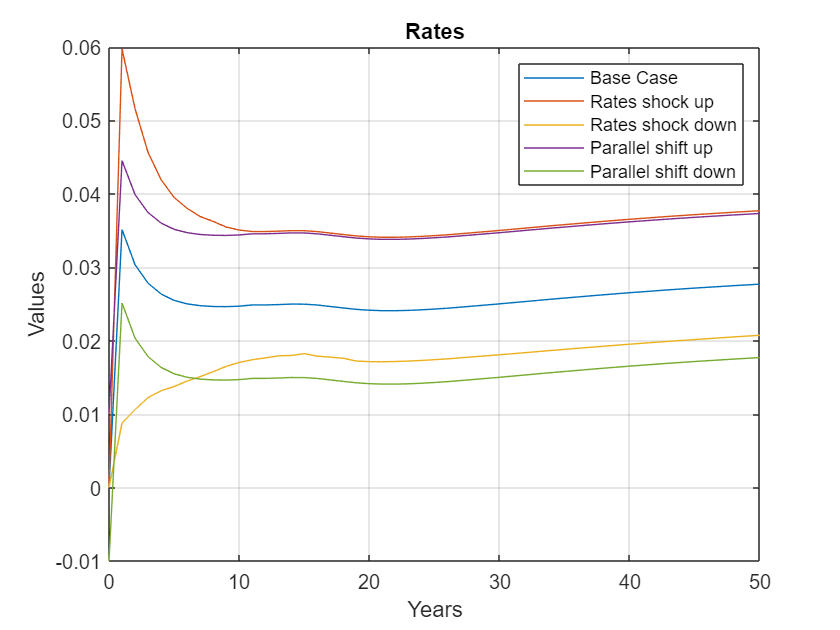

clear all
clc

fileName = 'PROGETTO';
opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 2;
opts.DataRange = 'A4:E54';
opts.VariableNames(1) = {'YEAR'};
opts.VariableNames(2) = {'RATES'};
opts.VariableNames(3) = {'SPOTRATES'};
opts.VariableNames(4) = {'DISCOUNTS'};
opts.VariableNames(5) = {'FORWARD'};
opts = setvartype(opts,'YEAR',{'double'});
opts = setvartype(opts,'RATES',{'double'});
opts = setvartype(opts,'SPOTRATES',{'double'});
opts = setvartype(opts,'DISCOUNTS',{'double'});
opts = setvartype(opts,'FORWARD',{'double'});

temp = readtable(fileName, opts);
years = temp.YEAR;
ratesBase = temp.RATES;

opts.DataRange = 'G4:K54';
temp = readtable(fileName, opts);
ratesShockUp = temp.RATES;

opts.DataRange = 'M4:Q54';
temp = readtable(fileName, opts);
ratesShockDown = temp.RATES;

opts.DataRange = 'S4:W54';
temp = readtable(fileName, opts);
ratesFakeUp = temp.RATES;

opts.DataRange = 'Y4:AC54';
temp = readtable(fileName, opts);
ratesFakeDown = temp.RATES;

figure()
plot(years, ratesBase)
hold on
plot(years, ratesShockUp)
plot(years, ratesShockDown)
plot(years, ratesFakeUp)
plot(years, ratesFakeDown)
grid on
legend('Base Case', 'Rates shock up', 'Rates shock down', 'Parallel shift up', 'Parallel shift down')
title('Rates')
xlabel('Years')
ylabel('Values')